## Polynomial 1

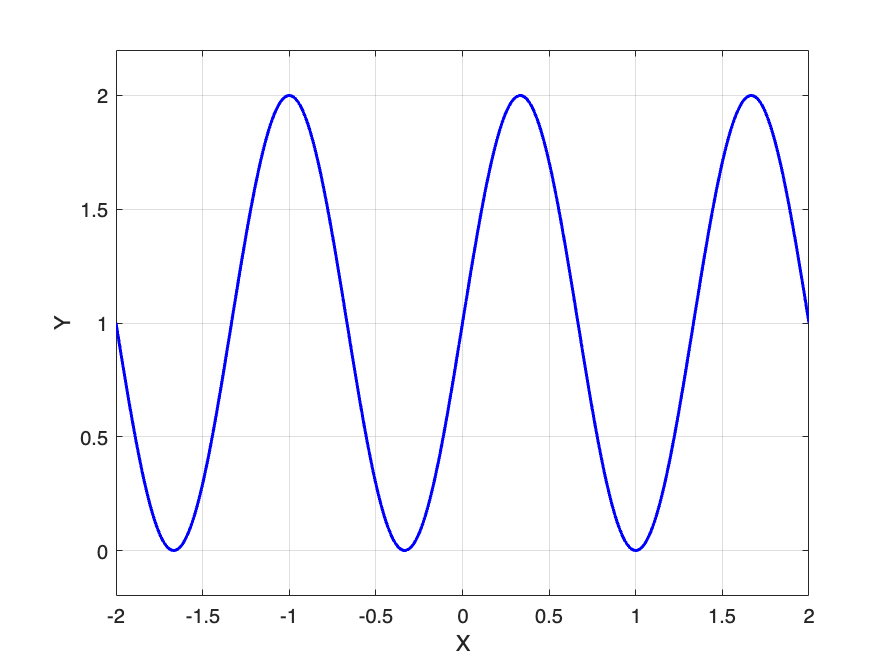

clc
clear all

polynomial1 = readmatrix("polynomials/Polinomio1.txt");
plotPolynomial(polynomial1);

% Hyperparameters
S_1 = 12; % <= 16
S_2 = 10; % <= 14
S_3 = 10; % <= 10
layers = [1 S_1 1];
transferFuncs = [3 1];

% Create MLP network
polynomial1_mlp = mlpNetwork(layers, transferFuncs);
disp('MLP created successfully')

MLP created successfully


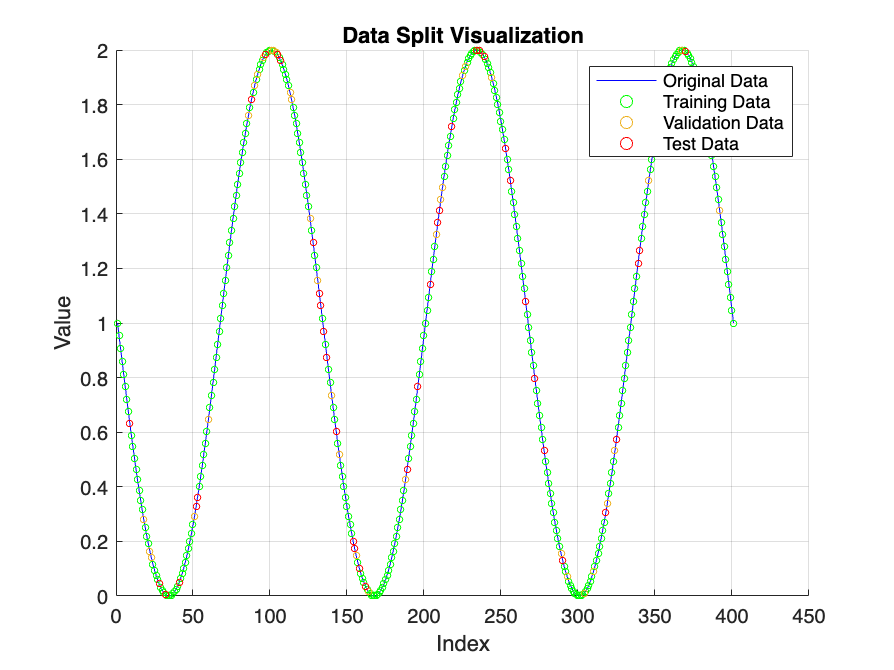

% Get data sets
[trainSet, valSet, testSet] = polynomial1_mlp.generateSets(polynomial1);

% Train MLP network
maxEpochs = 1000;           % Maximum number of epochs
learningRate = 0.005;       % Delta value 1e-2 to 1e-5
errorTrain = 0.001;         % Accuracy
epochVal = maxEpochs*0.1;   % How many epochs during the learning process will be a validation
numVal = 5;                 % The number of consecutive increments of validation error validation error to trigger early stopping
numberOfBatches = 10;       % Number of batches to train

batch = 1;                  % Batch number
stopCode = 0;               % Code indicating early stopping
while (stopCode ~= 1 && batch <= numberOfBatches)
    [polynomial1_mlp, stopCode] = polynomial1_mlp.train( ...
        trainSet, ...
        valSet, ...
        learningRate, ...
        maxEpochs, ...
        errorTrain, ...
        epochVal, ...
        numVal...
    );
    batch = batch + 1;
end
disp('Training finished');

Training finished


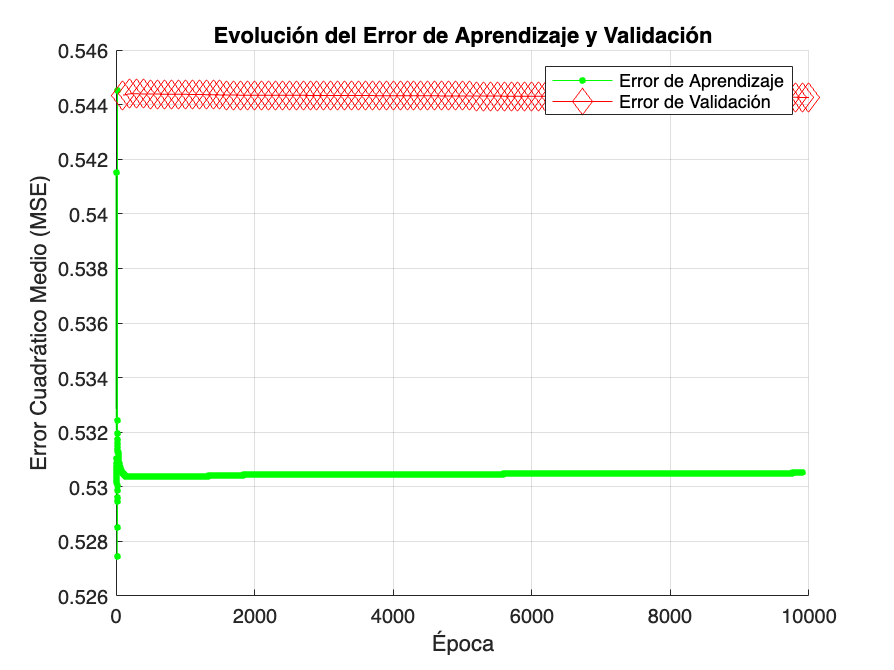

% Plot error
polynomial1_mlp.graphErroHistory(epochVal);

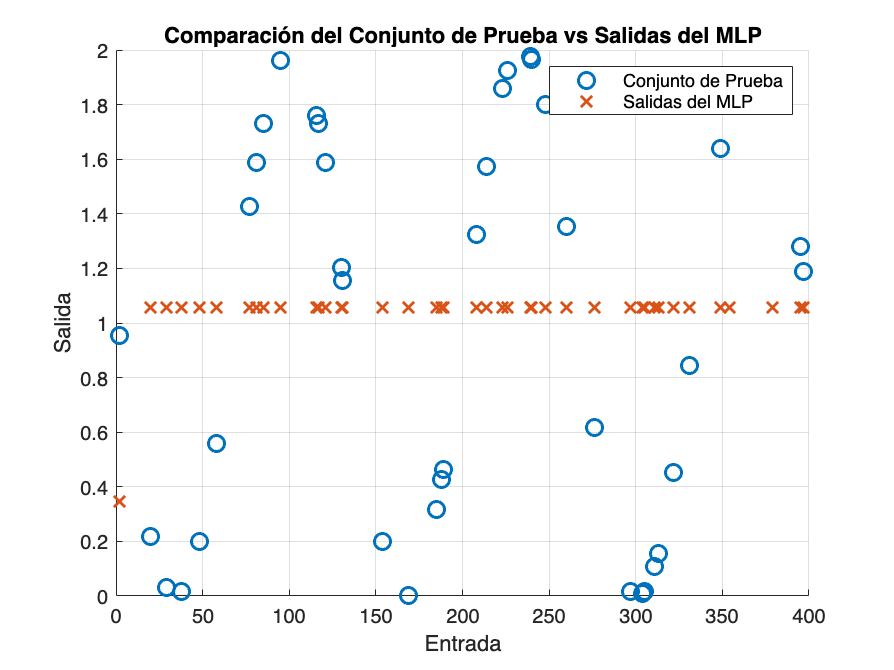

% Plot test
polynomial1_mlp.graphTestSet(testSet);

(Optional)

% Load previous Weights and Biases training values
polynomial1_mlp = loadWeightsAndBiases(polynomial1_mlp, 'trainPolynomial1');

% Load previous Error History
polynomial1_mlp = loadErrorHistory(polynomial1_mlp, 'trainPolynomial1');

% Save W B and errors
saveWeightsAndBiases(polynomial1_mlp, 'trainPolynomial1');

### Functions

function plotPolynomial(data)
    x = data(:, 1);
    y = data(:, 2);

    figure;
    plot(x, y, 'b-', 'LineWidth', 1.5);
    grid on;
    xlabel('X');
    ylabel('Y');

    %xPadding = (max(x) - min(x)) * 0.1; % 10% padding X
    yPadding = (max(y) - min(y)) * 0.1; % 10% padding Y
    %xlim([min(x) - xPadding, max(x) + xPadding]);
    ylim([min(y) - yPadding, max(y) + yPadding]);
end

function saveWeightsAndBiases(mlp, path)  
    % Write weights
    for i = 1:length(mlp.Weights)
        filename = fullfile(path, sprintf('weightsLayer%d.txt', i));
        writematrix(mlp.Weights{i}, filename);
    end
    
    % Write bias
    for i = 1:length(mlp.Biases)
        filename = fullfile(path, sprintf('biasesLayer%d.txt', i));
        writematrix(mlp.Biases{i}, filename);
    end

    % Write Error History
    writematrix(mlp.TrainingErrorHistory, fullfile(path, 'trainingErrorHistory.txt'));
    writematrix(mlp.ValidationErrorHistory, fullfile(path, 'validationErrorHistory.txt'));
end

function mlp = loadWeightsAndBiases(mlp, path)
    % Verify first if there is previous training data
    if ~isfolder(path)
        return;
    end
    
    num_layers = length(mlp.Weights);
    weights = cell(num_layers, 1);
    biases = cell(num_layers, 1);
    
    % Load Weights
    for i = 1:num_layers
        filename = fullfile(path, sprintf('weightsLayer%d.txt', i));
        if isfile(filename)
            weights{i} = readmatrix(filename);
        else
            return
        end
    end
    
    % Load Biases
    for i = 1:num_layers
        filename = fullfile(path, sprintf('biasesLayer%d.txt', i));
        if isfile(filename)
            biases{i} = readmatrix(filename);
        else
            return
        end
    end

    mlp = mlp.setWeightsAndBiases(weights, biases);
end

function mlp = loadErrorHistory(mlp, path)
    if (isfile(fullfile(path, 'trainingErrorHistory.txt')) && isfile(fullfile(path, 'validationErrorHistory.txt')))
        mlp = mlp.setErrorHistory( ...
                readmatrix(fullfile(path, 'trainingErrorHistory.txt')), ...
                readmatrix(fullfile(path, 'validationErrorHistory.txt')) ...
            );
    end
end